# SPINELEAF

%Variables to use
%X % Nodes in topology
%Y %k number of Shortest Paths
%Z %z Time required to compute the number of Shortest Paths

topology='SpineLeaf';
maxtopology=15;
max_N=25;
tries_for_toc=1000;

X(maxtopology-1,max_N)=0;
Y(maxtopology-1,max_N)=0;
Z(maxtopology-1,max_N)=0;
x(tries_for_toc)=1;

%Compute values
count=0;
for spines=2:1:maxtopology
    count=count+1;
    source=spines+1;
    G=graphTopology(false,false,topology,spines,spines);
    [dest h]=size(G.Nodes.Name);
    for N=1:max_N
        for z=1:tries_for_toc
        tic;
        paths=disjoint('SpineLeaf', 'edges', source, dest, N, false, spines, spines);
        %paths=disjoint('other', 'edges', source, dest, N, G, false, false);
        %paths=disjoint('other', 'edges', source, dest, N, G, false, true);
        %paths=disjoint('other', 'nodes', source, dest, N, G, false, false);
        %paths=disjoint('other', 'nodes', source, dest, N, G, false, true);
        u=toc;
        u=u*1000;
        x(z)=u;
        end
        X(count,N)=dest;
        Y(count,N)=N;
        Z(count,N)=mean(x);
    end
    spines
end

spines = 2

spines = 3

spines = 4

spines = 5

spines = 6

spines = 7

spines = 8

spines = 9

spines = 10

spines = 11

spines = 12

spines = 13

spines = 14

spines = 15

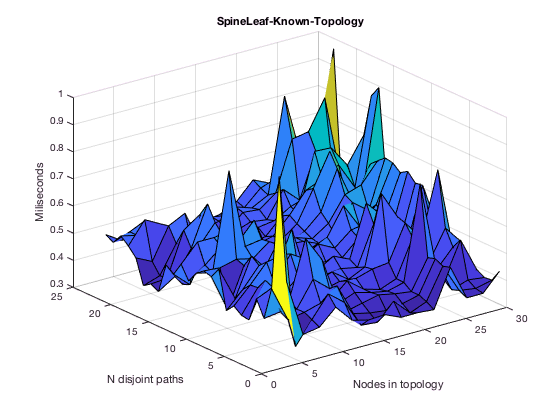

%Plot
tit='SpineLeaf-Known-Topology';
%tit='SpineLeaf-Edge-Normal';
%tit='SpineLeaf-Edge-Max';
%tit='SpineLeaf-Nodes-Normal';
%tit='SpineLeaf-Nodes-Max';

file=['Efficiency/SpineLeaf/',tit,'.mat'];
save(file, 'X', 'Y', 'Z');
fig=figure('Name',tit,'NumberTitle','off');
clf(fig);
surf(X,Y,Z);
xlabel('Nodes in topology');
ylabel('N disjoint paths');
zlabel('Miliseconds');
title(tit);
file=['Efficiency/SpineLeaf/',tit,'.fig'];
savefig(fig,file);
file=['Efficiency/SpineLeaf/',tit];
print(fig,file,'-dpng');

# VL2

topology='VL2';
maxmtopology=20;
max_N=20;
tries_for_toc=1000;

rows=(maxmtopology-2)/2;
X(rows,max_N)=0;
Y(rows,max_N)=0;
Z(rows,max_N)=0;
x(tries_for_toc)=1;

%Compute values
count=0;
for k=4:2:maxmtopology
    count=count+1;
    source=k*1.5+1;
    G=graphTopology(false,false,topology,k);
    [dest h]=size(G.Nodes.Name);
    for N=1:max_N
        for z=1:tries_for_toc
        tic;
        paths=disjoint('VL2', 'edges', source, dest, N, false, k);
        %paths=disjoint('other', 'edges', source, dest, N, G, false, false);
        %paths=disjoint('other', 'edges', source, dest, N, G, false, true);
        %paths=disjoint('other', 'nodes', source, dest, N, G, false, false);
        %paths=disjoint('other', 'nodes', source, dest, N, G, false, true);
        u=toc;
        u=u*1000;
        x(z)=u;
        end
        X(count,N)=dest;
        Y(count,N)=N;
        Z(count,N)=mean(x);
    end
    k
end

k = 4

k = 6

k = 8

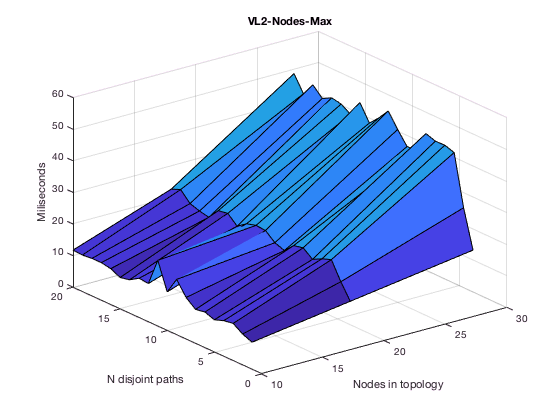

%Plot
tit='VL2-Known-Topology';
%tit='VL2-Edge-Normal';
%tit='VL2-Edge-Max';
%tit='VL2-Nodes-Normal';
%tit='VL2-Nodes-Max';

file=['Efficiency/VL2/',tit,'.mat'];
save(file, 'X', 'Y', 'Z');
fig=figure('Name',tit,'NumberTitle','off');
clf(fig);
surf(X,Y,Z);
xlabel('Nodes in topology');
ylabel('N disjoint paths');
zlabel('Miliseconds');
title(tit);
file=['Efficiency/VL2/',tit,'.fig'];
savefig(fig,file);
file=['Efficiency/VL2/',tit];
print(fig,file,'-dpng');

# Portland

%Variables to use
%X %k in VL2
%Y %k number of Shortest Paths
%Z %z Time required to compute the number of Shortest Paths

topology='Portland';
maxmtopology=6;
max_N=20;
tries_for_toc=100;

rows=maxmtopology/2;
X(rows,max_N)=0;
Y(rows,max_N)=0;
Z(rows,max_N)=0;
x(tries_for_toc)=1;

%Compute values
count=0;
for k=2:2:maxmtopology
    count=count+1;
    source=(k/2)^2*3+1;
    G=graphTopology(false,false,topology,k);
    [dest h]=size(G.Nodes.Name);
    for N=1:max_N
        for z=1:tries_for_toc
        tic;
        %paths=disjoint('other', 'edges', source, dest, N, G, false, false);
        %paths=disjoint('other', 'edges', source, dest, N, G, false, true);
        %paths=disjoint('other', 'nodes', source, dest, N, G, false, false);
        paths=disjoint('other', 'nodes', source, dest, N, G, false, true);
        u=toc;
        u=u*1000;
        x(z)=u;
        end
        X(count,N)=dest;
        Y(count,N)=N;
        Z(count,N)=mean(x);
    end
    k
end

k = 2

k = 4

k = 6

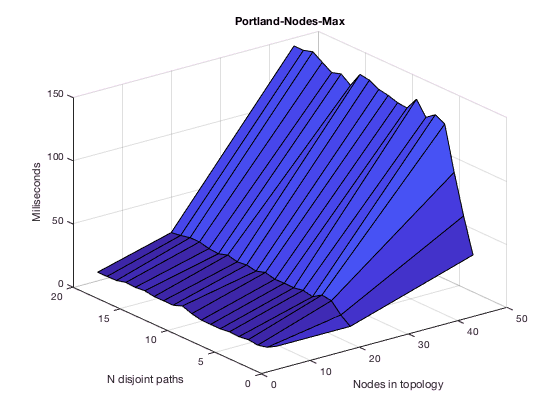

%Plot
%tit='Portland-Edge-Normal';
%tit='Portland-Edge-Max';
%tit='Portland-Nodes-Normal';
tit='Portland-Nodes-Max';

file=['Efficiency/Portland/',tit,'.mat'];
save(file, 'X', 'Y', 'Z');
fig=figure('Name',tit,'NumberTitle','off');
clf(fig);
surf(X,Y,Z);
xlabel('Nodes in topology');
ylabel('N disjoint paths');
zlabel('Miliseconds');
title(tit);
file=['Efficiency/Portland/',tit,'.fig'];
savefig(fig,file);
file=['Efficiency/Portland/',tit];
print(fig,file,'-dpng');

# Altoona Facebook

%Variables to use
%X % Nodes in topology
%Y %k number of Shortest Paths
%Z %z Time required to compute the number of Shortest Paths

topology='AltoonaFacebook';
maxmtopology=2;
max_N=10;
tries_for_toc=10;

X(maxmtopology,max_N)=0;
Y(maxmtopology,max_N)=0;
Z(maxmtopology,max_N)=0;
x(tries_for_toc)=1;

%Compute values
count=0;
for m=1:1:maxmtopology
    count=count+1;
    G=graphTopology(false,false,topology,m,m);
    [dest h]=size(G.Nodes.Name);
    source=dest-48*m+1;
    for N=1:max_N
        for z=1:tries_for_toc
        tic;
        %paths=disjoint('other', 'edges', source, dest, N, G, false, false);
        %paths=disjoint('other', 'edges', source, dest, N, G, false, true);
        %paths=disjoint('other', 'nodes', source, dest, N, G, false, false);
        paths=disjoint('other', 'nodes', source, dest, N, G, false, true);
        u=toc;
        u=u*1000;
        x(z)=u;
        end
        X(count,N)=dest;
        Y(count,N)=N;
        Z(count,N)=mean(x);
    end
    m
end

m = 1

m = 2

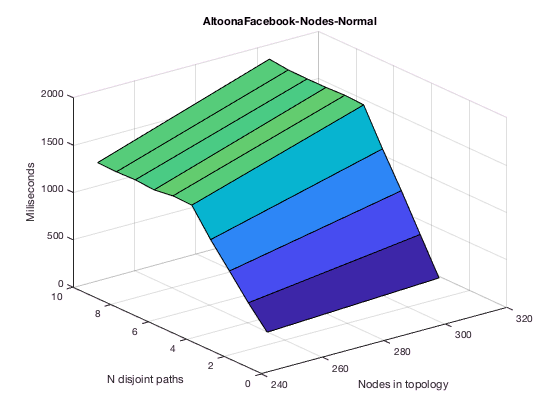

%Plot
%tit='AltoonaFacebook-Edge-Normal';
%tit='AltoonaFacebook-Edge-Max';
%tit='AltoonaFacebook-Nodes-Normal';
tit='AltoonaFacebook-Nodes-Max';

file=['Efficiency/AltoonaFacebook/',tit,'.mat'];
save(file, 'X', 'Y', 'Z');
fig=figure('Name',tit,'NumberTitle','off');
clf(fig);
surf(X,Y,Z);
xlabel('Nodes in topology');
ylabel('N disjoint paths');
zlabel('Miliseconds');
title(tit);
file=['Efficiency/AltoonaFacebook/',tit,'.fig'];
savefig(fig,file);
file=['Efficiency/AltoonaFacebook/',tit];
print(fig,file,'-dpng');